clear;
% Read training images
data = imageDatastore('./svm_data/TrainImages','IncludeSubfolders',true,'LabelSource','foldernames');

% Display label counts
tbl = countEachLabel(data)

tbl = 2×2 table
     Label      Count
    ________    _____
    Others       436 
    Vehicles     108 

% Split and train images
[trainingSet, validationSet] = splitEachLabel(data, 0.7, 'randomize');
bag = bagOfFeatures(trainingSet, 'Verbose', true);


Creating Bag-Of-Features.
-------------------------
* Image category 1: Others
* Image category 2: Vehicles
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 381 images...done. Extracted 24042 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 2 has the least number of strongest features: 4629.
** Using the strongest 4629 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 9258
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 29/100 iterations (~0.18 seconds/iteration)...converged in 29 iterations.

* Finished creating Bag-Of-Features



categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);


Training an image category classifier for 2 categories.
--------------------------------------------------------
* Category 1: Others
* Category 2: Vehicles

* Encoding features for 381 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



% Create confusion matrix
confMatrix = evaluate(categoryClassifier, validationSet)


Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: Others
* Category 2: Vehicles

* Evaluating 163 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                   PREDICTED
KNOWN       | Others   Vehicles   
----------------------------------
Others      | 0.89     0.11       
Vehicles    | 0.13     0.88       

* Average Accuracy is 0.88.



confMatrix =       0.89313      0.10687
        0.125        0.875


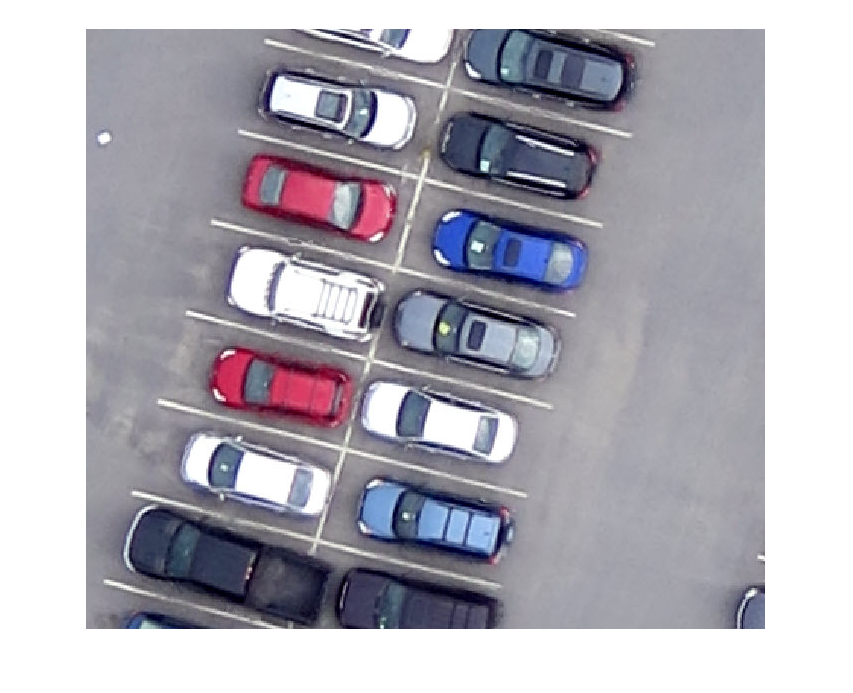

% Predict on test images
img = imread('./svm_data/TestImages/Test1.jpg');
figure; imshow(img)

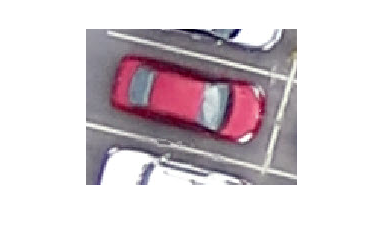


car1 = imcrop(img,[132 100 210 155]);
figure; imshow(car1);

predict_class(categoryClassifier, car1)

ans = 1×1 cell array
    {'Others'}

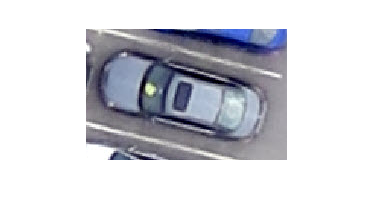


car2 = imcrop(img,[295 240 200 130]);
figure; imshow(car2);

predict_class(categoryClassifier, car2)

ans = 1×1 cell array
    {'Vehicles'}

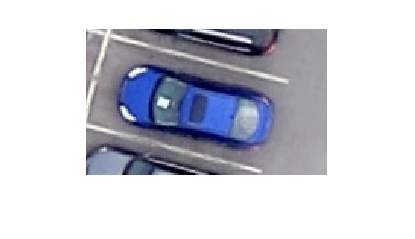


car3 = imcrop(img,[315 145 240 145]);
figure; imshow(car3);

predict_class(categoryClassifier, car3)

ans = 1×1 cell array
    {'Vehicles'}

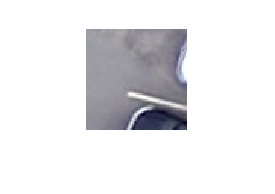


other1 = imcrop(img,[5 400 100 100]);
figure; imshow(other1);

predict_class(categoryClassifier, other1)

ans = 1×1 cell array
    {'Others'}

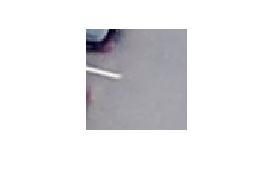


other2 = imcrop(img,[512 60 100 100]);
figure; imshow(other2);

predict_class(categoryClassifier, other2)

ans = 1×1 cell array
    {'Others'}

function predict_class(classifier, img)

[labelIdx, ~] = predict(classifier, img);
classifier.Labels(labelIdx)

end